### **Load Data**

%  The first 2 columns contains the features and the 3rd column contains the maintenance decision 
%  1 = maintenance is needed and 0 = not needed

Cross validation data

data = load('CrossData.csv');
Xcv = data(:, [1, 2]); 
ycv = data(:, 3);

Test Data

data = load('TestData.csv');
Xtest = data(:, [1, 2]); 
ytest = data(:, 3);

Train Data

data = load('TrainData.csv');
TrainX = data(:, [1, 2]); 
TrainY = data(:, 3);

Add cross data to training data

TrainX = [TrainX;Xcv];
TrainY = [TrainY;ycv];

PCA method for data visualization 

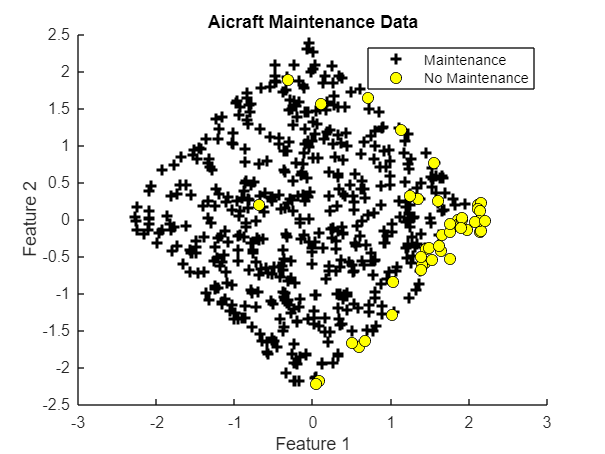

[Xtest, meu, sigma] = FeatureNormalize(Xtest);

% Feature Normalization
[X_norm, meu, sigma] = FeatureNormalize(TrainX);

%  Run PCA
[U, S] = PCA(X_norm);

%  Project the data onto K  dimension
K = 2;
Z = ProjectData(X_norm, U, K);

%  Plot the normalized dataset (from pca)
PlotData(Z, TrainY);
xlabel('Feature 1');
ylabel('Feature 2');
legend('Maintenance', 'No Maintenance');
title('Aicraft Maintenance Data');

### Cost and gradient

% implementing cost and gradient ( logistic regression )
TrainX = X_norm;

%  Data matrix setup
[m, n] = size(TrainX);

% Add intercept term to X
TrainX = [ones(m, 1) TrainX];

% Initialize fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display initial cost and gradient
[cost, gradient] = CostFunc(initial_theta, TrainX, TrainY);

### Optimisation (through fminunc)

% Set fminunc options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, cost] = fminunc(@(theta)(CostFunc(theta, TrainX, TrainY)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>




% Plot the Decision Boundary
PlotDecisionBoundary(theta, Z, TrainY);

hold on;
xlabel('Feature projection - 1');
ylabel('Feature projection - 2');
title('Aicraft Maintenance Data');
hold off;


% 
[p, F1] = predict(theta, TrainX, TrainY);
fprintf('\nTrain Accuracy: %f\nF1 score: %f\n\n', mean(double(p == TrainY)) * 100, F1);


Train Accuracy: 95.045872
F1 score: 0.973659




[mtest, ntest] = size(Xtest);
Xtest = [ones(mtest, 1) Xtest];


% Randomly select a row from dataset and make predictions
fprintf('\n Randomly Selected Row: \n')


 Randomly Selected Row: 


RowNumber = randperm(size(Xtest,1),1)

RowNumber = 24

RowFeature = Xtest(RowNumber,:);
prob = Sigmoid(RowFeature.*theta);

if(prob>=0.65)
 fprintf('Condition: needs maintenance \n\n')
 hold on
else
 fprintf('Condition: does not need maintenance \n\n')
 hold on
end

Condition: needs maintenance 




% Predicting condition based on the user input
fprintf('\n \n Enter the aircraft parameters: \n\n');


 
 Enter the aircraft parameters: 



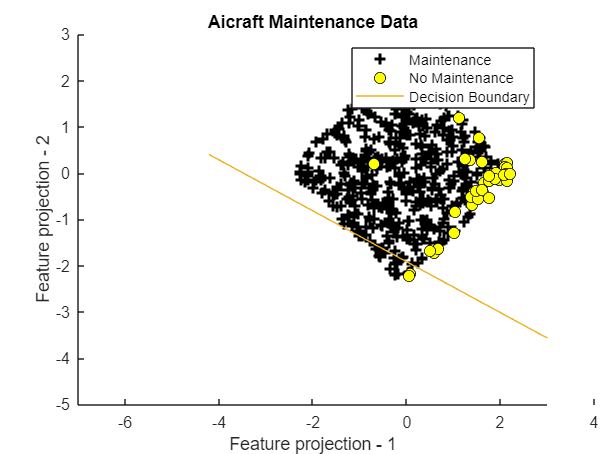


 Condition: NEEDS MAINTENANCE 



I(1,1)=input('Enter age: ');
I(1,2)=input('Enter operational hours: ');
I;

% User input data processing
[I, meu, sigma] = FeatureNormalize(I);
prob=Sigmoid(I*theta);


if(prob>=0.5)
 fprintf('\n Condition: NEEDS MAINTENANCE \n\n')
 hold on
else
 fprintf('\n Condition: DOES NOT NEED MAINTENANCE \n\n')
 hold on
end


% Test set accuracy
[ptest, F1test] = predict(theta, Xtest, ytest);
fprintf('Test Accuracy: %f\nF1 score: %f\n', mean(double(ptest == ytest)) * 100, F1test);

Test Accuracy: 92.028986
F1 score: 0.957198
